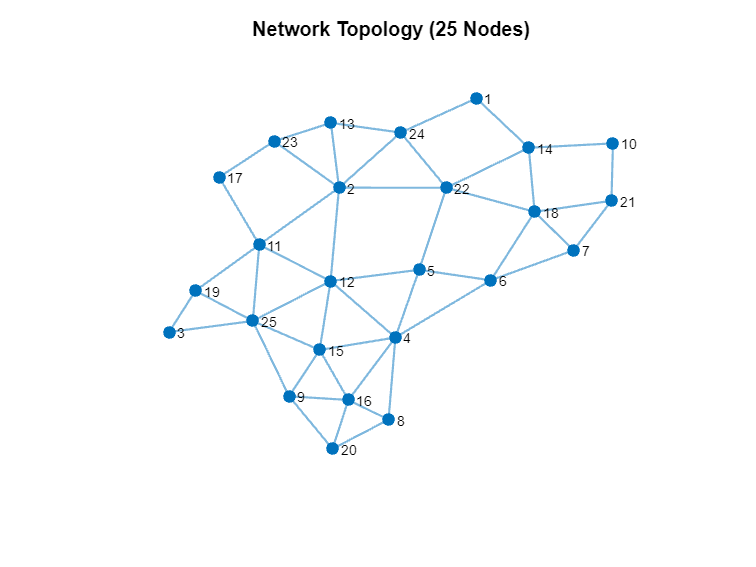

% FLOOD_ROUTING_SIMULATION.M
% -------------------------------------------------------------------------
% Description:
%   Simulates packet flooding in a 25-node network with duplicate detection
%   and congestion analysis. Implements TTL-limited flooding algorithm with
%   comprehensive statistics collection and visualisation.
%
% Key Functionality:
%   1. Network initialisation from adjacency matrix
%   2. Packet flooding with TTL management
%   3. Duplicate packet detection and counting
%   4. Path tracking and delivery confirmation
%   5. Congestion monitoring and visualisation
%
% Inputs:
%   'network_topology_undirected.mat' - Predefined network adjacency matrix
%
% Outputs:
%   1. Console statistics on packet delivery and duplicates
%   2. Visualisations of network topology and packet paths
%   3. Congestion heatmap and final network state
%
% Parameters:
%   - TTL: Time-To-Live for packets (default: 10 hops)
%   - T_max: Simulation duration (default: 50 timesteps)
%   - packetID: Unique identifier for tracking (default: 2631617)
%   - source/destination: Node 3 to Node 10 by default
%
% Created: 19-04-2025
% Last Modified: 22-04-2025
% Author: Harris Lee
% Student ID: 2631617
% -------------------------------------------------------------------------

clc; clear all;

% Load network topology
load('network_topology_undirected.mat');  % Must contain 'adjMatrixUndirected'
networkTopology = adjMatrixUndirected;
numNodes = size(networkTopology, 1);

% Parameters
TTL = 10;
T_max = 50;
packetID = 2631617;

% Create graph object
network = graph(networkTopology);

% Define initial packet
initialPacket = struct('source', 3, ...
                       'destination', 10, ...
                       'ttl', TTL, ...
                       'path', [], ...
                       'id', packetID, ...
                       'sender', NaN);  % No sender initially

% Initialise node structures
nodes(numNodes).packetQueue = {};
for i = 1:numNodes
    nodes(i).packetQueue = {};
    nodes(i).receivedIDs = [];
    nodes(i).congestionLog = zeros(1, T_max);
    nodes(i).arrivalCount = 0;
    nodes(i).duplicateCount = 0;
end
nodes(initialPacket.source).packetQueue{end+1} = initialPacket;

duplicateCount = 0;
destinationDuplicateCount = 0;
delivered = false;
finalPath = [];

% Plot initial topology
layoutType = 'force';
figure('Color', 'w');
plot(network, 'Layout', layoutType, 'LineWidth', 1.2, 'MarkerSize', 6);
title('Network Topology (25 Nodes)');
axis off;


% Time loop
for t = 1:T_max
    disp(['--- Time Step ', num2str(t), ' ---']);
    
    tempQueues = cell(numNodes, 1);  % Store next timestep packets
    
    for nodeID = 1:numNodes
        queue = nodes(nodeID).packetQueue;
        nodes(nodeID).congestionLog(t) = length(queue);  % Log queue length
        
        if isempty(queue)
            continue;
        end
        
        % Process one packet per timestep
        packet = queue{1};
        nodes(nodeID).packetQueue = queue(2:end);

        % Check for duplicate
        isDuplicate = ismember(packet.id, nodes(nodeID).receivedIDs);
        if isDuplicate
            duplicateCount = duplicateCount + 1;
            nodes(nodeID).duplicateCount = nodes(nodeID).duplicateCount + 1;
            if nodeID == initialPacket.destination
                destinationDuplicateCount = destinationDuplicateCount + 1;
                disp(['Duplicate packet arrived at DESTINATION at t=', num2str(t)]);
            end
        end

        nodes(nodeID).arrivalCount = nodes(nodeID).arrivalCount + 1;

        % Log ID if first time
        if ~isDuplicate
            nodes(nodeID).receivedIDs(end+1) = packet.id;
        end

        % If first arrival at destination
        if nodeID == packet.destination && ~delivered
            finalPath = [packet.path, nodeID];
            disp(['Packet reached destination at t=', num2str(t), ' via path: ', num2str(finalPath)]);
            delivered = true;
        end

        % Forward to all neighbors (except the sender)
        if packet.ttl > 0 && nodeID ~= packet.destination
            neighbours = find(networkTopology(nodeID, :) == 1);
            for neighbour = neighbours
                if neighbour == packet.sender
                    continue;  % Skip backward
                end
                newPacket = packet;
                newPacket.ttl = packet.ttl - 1;
                newPacket.path = [packet.path, nodeID];
                newPacket.sender = nodeID;
                tempQueues{neighbour}{end+1} = newPacket;
            end
        end
    end

    % Update queues
    for i = 1:numNodes
        nodes(i).packetQueue = [nodes(i).packetQueue, tempQueues{i}];
    end
end

--- Time Step 1 ---
--- Time Step 2 ---
--- Time Step 3 ---
--- Time Step 4 ---
--- Time Step 5 ---
--- Time Step 6 ---
--- Time Step 7 ---


Packet reached destination at t=7 via path: 3  19  11   2  22  14  10


--- Time Step 8 ---


Duplicate packet arrived at DESTINATION at t=8


--- Time Step 9 ---


Duplicate packet arrived at DESTINATION at t=9


--- Time Step 10 ---


Duplicate packet arrived at DESTINATION at t=10


--- Time Step 11 ---


Duplicate packet arrived at DESTINATION at t=11


--- Time Step 12 ---


Duplicate packet arrived at DESTINATION at t=12


--- Time Step 13 ---


Duplicate packet arrived at DESTINATION at t=13


--- Time Step 14 ---


Duplicate packet arrived at DESTINATION at t=14


--- Time Step 15 ---


Duplicate packet arrived at DESTINATION at t=15


--- Time Step 16 ---


Duplicate packet arrived at DESTINATION at t=16


--- Time Step 17 ---


Duplicate packet arrived at DESTINATION at t=17


--- Time Step 18 ---


Duplicate packet arrived at DESTINATION at t=18


--- Time Step 19 ---


Duplicate packet arrived at DESTINATION at t=19


--- Time Step 20 ---


Duplicate packet arrived at DESTINATION at t=20


--- Time Step 21 ---


Duplicate packet arrived at DESTINATION at t=21


--- Time Step 22 ---


Duplicate packet arrived at DESTINATION at t=22


--- Time Step 23 ---


Duplicate packet arrived at DESTINATION at t=23


--- Time Step 24 ---


Duplicate packet arrived at DESTINATION at t=24


--- Time Step 25 ---


Duplicate packet arrived at DESTINATION at t=25


--- Time Step 26 ---


Duplicate packet arrived at DESTINATION at t=26


--- Time Step 27 ---


Duplicate packet arrived at DESTINATION at t=27


--- Time Step 28 ---


Duplicate packet arrived at DESTINATION at t=28


--- Time Step 29 ---


Duplicate packet arrived at DESTINATION at t=29


--- Time Step 30 ---


Duplicate packet arrived at DESTINATION at t=30


--- Time Step 31 ---


Duplicate packet arrived at DESTINATION at t=31


--- Time Step 32 ---


Duplicate packet arrived at DESTINATION at t=32


--- Time Step 33 ---


Duplicate packet arrived at DESTINATION at t=33


--- Time Step 34 ---


Duplicate packet arrived at DESTINATION at t=34


--- Time Step 35 ---


Duplicate packet arrived at DESTINATION at t=35


--- Time Step 36 ---


Duplicate packet arrived at DESTINATION at t=36


--- Time Step 37 ---


Duplicate packet arrived at DESTINATION at t=37


--- Time Step 38 ---


Duplicate packet arrived at DESTINATION at t=38


--- Time Step 39 ---


Duplicate packet arrived at DESTINATION at t=39


--- Time Step 40 ---


Duplicate packet arrived at DESTINATION at t=40


--- Time Step 41 ---


Duplicate packet arrived at DESTINATION at t=41


--- Time Step 42 ---


Duplicate packet arrived at DESTINATION at t=42


--- Time Step 43 ---


Duplicate packet arrived at DESTINATION at t=43


--- Time Step 44 ---


Duplicate packet arrived at DESTINATION at t=44


--- Time Step 45 ---


Duplicate packet arrived at DESTINATION at t=45


--- Time Step 46 ---


Duplicate packet arrived at DESTINATION at t=46


--- Time Step 47 ---


Duplicate packet arrived at DESTINATION at t=47


--- Time Step 48 ---


Duplicate packet arrived at DESTINATION at t=48


--- Time Step 49 ---


Duplicate packet arrived at DESTINATION at t=49


--- Time Step 50 ---


Duplicate packet arrived at DESTINATION at t=50



% -------------------- STATS & REPORTING --------------------
disp(' ');

disp(['Number of duplicate packets received at DESTINATION node (' num2str(initialPacket.destination) '): ', num2str(destinationDuplicateCount)]);

Number of duplicate packets received at DESTINATION node (10): 43


disp('--- Node-Level Packet Statistics ---');

--- Node-Level Packet Statistics ---


for i = 1:numNodes
    fprintf('Node %2d: Total Arrivals = %3d | Duplicates = %2d\n', ...
            i, nodes(i).arrivalCount, nodes(i).duplicateCount);
end

Node  1: Total Arrivals =  45 | Duplicates = 44
Node  2: Total Arrivals =  47 | Duplicates = 46
Node  3: Total Arrivals =  48 | Duplicates = 47
Node  4: Total Arrivals =  47 | Duplicates = 46
Node  5: Total Arrivals =  47 | Duplicates = 46
Node  6: Total Arrivals =  46 | Duplicates = 45
Node  7: Total Arrivals =  45 | Duplicates = 44
Node  8: Total Arrivals =  46 | Duplicates = 45
Node  9: Total Arrivals =  48 | Duplicates = 47
Node 10: Total Arrivals =  44 | Duplicates = 43
Node 11: Total Arrivals =  48 | Duplicates = 47
Node 12: Total Arrivals =  48 | Duplicates = 47
Node 13: Total Arrivals =  46 | Duplicates = 45
Node 14: Total Arrivals =  45 | Duplicates = 44
Node 15: Total Arrivals =  48 | Duplicates = 47
Node 16: Total Arrivals =  47 | Duplicates = 46
Node 17: Total Arrivals =  47 | Duplicates = 46
Node 18: Total Arrivals =  45 | Duplicates = 44
Node 19: Total Arrivals =  48 | Duplicates = 47
Node 20: Total Arrivals =  47 | Duplicates = 46
Node 21: Total Arrivals =  44 | Duplicat

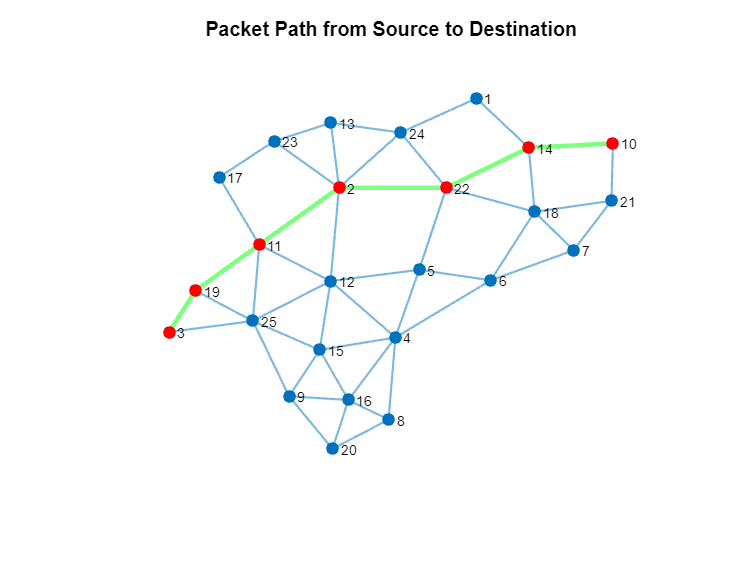


% -------------------- VISUALISE FOUND PATH --------------------
if ~isempty(finalPath)
    figure('Color', 'w');
    h = plot(network, 'Layout', layoutType, 'LineWidth', 1.2, 'MarkerSize', 6);
    highlight(h, finalPath, 'EdgeColor', 'g', 'LineWidth', 2.5);  % Highlight path
    highlight(h, finalPath, 'NodeColor', 'r');
    title('Packet Path from Source to Destination');
    axis off;
end

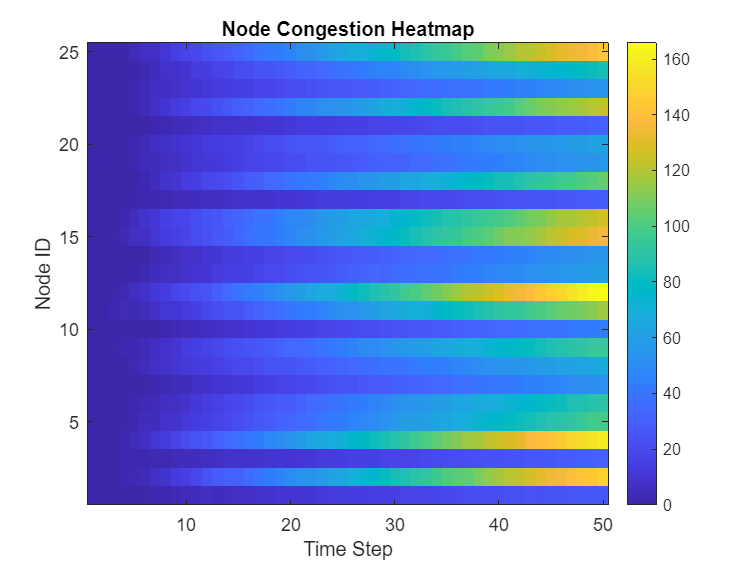


% -------------------- HEATMAP --------------------
congestionMatrix = cell2mat(arrayfun(@(x) x.congestionLog', nodes, 'UniformOutput', false));

figure('Color', 'w');
imagesc(congestionMatrix');
colormap parula;
colorbar;
xlabel('Time Step');
ylabel('Node ID');
title('Node Congestion Heatmap');
set(gca, 'YDir', 'normal');

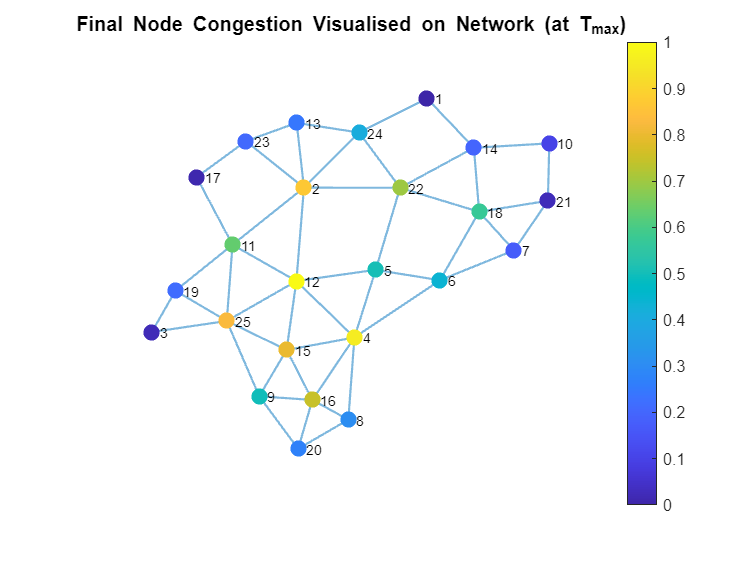


% -------------------- FINAL CONGESTION TOPOLOGY --------------------
finalCongestion = mean(congestionMatrix, 1);      
normCongestion = rescale(finalCongestion);       % Normalise 0 to 1

figure('Color', 'w');
h = plot(network, 'Layout', layoutType, 'NodeCData', normCongestion, ...
         'MarkerSize', 8, 'LineWidth', 1.2);
colormap parula;
colorbar;
title('Final Node Congestion Visualised on Network (at T_{max})');
axis off;